# ELEC 4700 Assignment 3 MC and FD Methods

### Part 1: Upgrading Monte-Carlo simulator to include the effect of an Electric Field on the model

The goal is to create a constant electric field across the region from left to right. The effect of an electric field on each electron in this case will manifest as an acceleration, forcing the electron along the positive x-axis. To accomplish this the following steps were performed.

- Let $V_{\mathrm{const}}$ be a voltage applied @$x=0$


$$V_{\mathrm{const}} =0\ldotp 1V$$


- The electric field will be constant along the **Length** of the region


$$\mathrm{Length}=200\mathrm{nm}$$



$$E_X =\frac{V_{\mathrm{const}} }{\mathrm{Length}}=0\ldotp 5{\mathrm{x10}}^6 \frac{V}{m}$$


- To obtain the acceleration, the force from the electric field on each particle in the x direction is equivalent to the elementary charge.


$$F_X =q_e *E_x =80\ldotp 12{\mathrm{x10}}^{-15} N$$


- The acceleration is based off the effective mass of the particle


$$a_X =\frac{F_X }{m_n }=338\ldotp 26{\mathrm{x10}}^{19} \frac{m}{s^2 },\mathrm{where}\;m_n =0\ldotp 26m_0$$


- Note that the above can be done in the y direction as well to give a complete 2-dimentional force on each electron.

The following is a simulation of 30000 electrons after 100 time steps. A **constant voltage of 0.5V **is used to more clearly demonstrate the effect of the electric field. There is no electric field in the y direction.

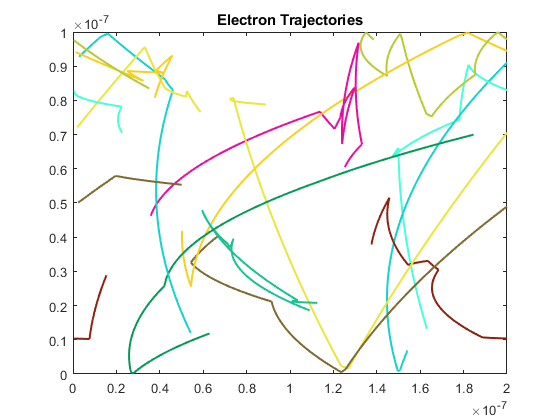

% MC Settings
eCount = 30000;      % Total number of electrons
ePlotted = 10;      % Number of Electrons Plotted
dt = 10e-15;        % Time step 10fs -> -(Width/100)/vT
nt = 100;           % Simulation steps
tStop = nt * dt;	% Stop Time

% Region settings
Length = 200e-9;
Width = 100e-9;

% Electron Properties
kB = 1.38066e-23;   % J/K 
m0 = 9.11e-31;      % Rest Mass
mn = 0.26*m0;       % Effective Mass
qe = 1.602e-19;     % Charge of an Electron 

% Thermal Velocity
Temp = 300;     % K
vT = sqrt((2*kB*Temp)/mn);

% Scattering Settings
% probability of scattering
toggleScatter = 1;    % Toggle Scattering OFF(0) ON(1)
tmin = 0.2e-12;
pScatter = 1 - exp(-dt/tmin);

% Electric Field Settings
constV = 0.5;       % Constant voltage applied
Ex = constV/Length;  % electric field along the x-axis
Ey = 0;
Fx = qe * Ex;
Fy = qe * Ey;

% Initializing all electrons with a position and velocity
eObj = struct('x', 0, 'y', 0, 'vx', 0, 'vy', 0, ...
                        'vm', 0, 'vdx', 0, 'vdy', 0);
eCol = rand(eCount,3);   % Random colours for plotting
for i = 1 : eCount
    eObj(i).x = rand()*Length;
    eObj(i).y = rand()*Width;
    eObj(i).vx = (sqrt(vT^2 / 2)*randn(1,1));
    eObj(i).vy = (sqrt(vT^2 / 2)*randn(1,1));
    eObj(i).vm = sqrt(eObj(i).vx^2 + eObj(i).vy^2);
end

t = 0;          % Init time
counter = 2;    % Init Counter
while t < tStop
    t = t + dt;	% Incrementing Time
    
    prevX = [eObj(:).x];    % Previous X location
    prevY = [eObj(:).y];    % Previous Y location
    for i = 1 : eCount
        
        % Updating position
        eObj(i).x = prevX(i) + eObj(i).vx * dt;
        eObj(i).y = prevY(i) + eObj(i).vy * dt;
        
        % Scattering effect - Randomize direction/magnitude of velocity
        % Probability of scattering based on p.
        if pScatter > rand() && toggleScatter	% 'if true'
            eObj(i).vx = (sqrt(vT^2 / 2)*randn(1,1));
            eObj(i).vy = (sqrt(vT^2 / 2)*randn(1,1));
        end
        
        % Updating the velocities with the effect of E-Field
        eObj(i).vx = eObj(i).vx + 1/2*Fx/mn*dt;
        eObj(i).vy = eObj(i).vy + 1/2*Fy/mn*dt;
        
        % Drift velocity calculation
        dx = eObj(i).x - prevX(i);
        eObj(i).vdx = dx/dt;
        
        % Magnitude of velocity
        eObj(i).vm = sqrt(eObj(i).vx.^2 + eObj(i).vy.^2);
        
        % Top and Bottom Boundary Conditions
        if eObj(i).y > Width % y = 200nm boundary 
            diff = eObj(i).y - Width;
            eObj(i).y = Width - diff;
            eObj(i).vy = -eObj(i).vy;
        end
        if eObj(i).y < 0   % y = 0nm boundary
            diff = -eObj(i).y;
            eObj(i).y = diff;
            eObj(i).vy = -eObj(i).vy;
        end
        
        % Plotting Electrons
        if (i <= ePlotted)
            % Plotting previous and current position
            subplot(1,1,1);
            p = plot( [prevX(i), eObj(i).x], ...
                [prevY(i), eObj(i).y], ...
                'LineWidth', 1.5);
            p.Color = eCol(i,:);        % Attributing unique colour
            axis([0,Length,0,Width]);	% Plot Axis' set
            title('Electron Trajectories');
            hold on
        end
        
        % Left hand and Right hand side Boundary Conditions
        if eObj(i).x > Length   % x = 100nm boundary
            eObj(i).x = eObj(i).x - Length;
        end
        if eObj(i).x < 0   % x = 0nm boundary
            eObj(i).x = eObj(i).x + Length;
        end
        
    end
    pause(0.01);	% Delay for animation
    
    % Calculating the Average Temperature over time
    allTemperatures = ( ([eObj(:).vm].^2) .* mn ) ./ (kB*2);
    Temp(:,counter) = mean(allTemperatures);
    
    % Calculating drift current density over time
    Jnx(:,counter) = qe*10e19*mean([eObj(:).vdx]);
    
    Time(:,counter) = t;        % Recording time in a vector
    counter = counter + 1;      % Incrementing Sim Counter
end
hold off

The electrons tend to curve in the direction of the of the force applied. When the electron scatters it is rethermalized which is why some electrons will change direction but then be forced back into the positive x direction.

The following are some extracted properties of the electrons over time. The density and temperature is mostly uniform. Over time the temperature and drift current density seem to saturate. Demonstrating how the material being modelled has a potential 'rest' state.

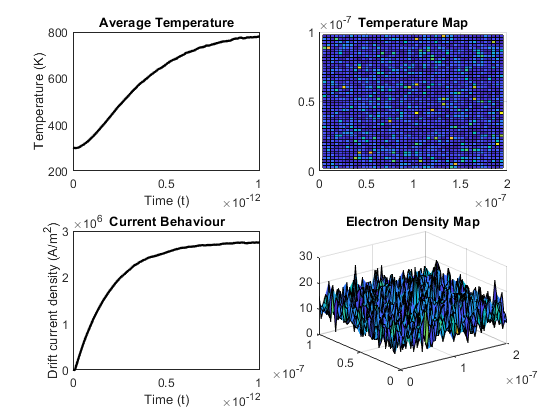

figure('name', 'Extracted Properties')
divX = 50;  divY = 50;  % plot settings

% Plotting the Average Temperature over time
subplot(2,2,1), plot(Time, Temp, 'k', 'LineWidth',1.75);
xlabel('Time (t)'), ylabel('Temperature (K)');
title('Average Temperature');

% Plotting Temperature Map
xv = linspace(min([eObj(:).x]), max([eObj(:).x]), divX);
yv = linspace(min([eObj(:).y]), max([eObj(:).y]), divY);
[X,Y] = meshgrid(xv, yv);
Z = griddata([eObj(:).x],[eObj(:).y],allTemperatures,X,Y); % Mapping Temps
subplot(2, 2, 2); 
surf(X, Y, Z),title('Temperature Map');
axis([0,Length,0,Width]); view([-0 90]);  % Plot Axis' set

% Plotting drift current density over time
subplot(2,2,3), plot(Time, Jnx, 'k', 'LineWidth',1.75);
xlabel('Time (t)'), ylabel('Drift current density (A/m^2)');
title('Current Behaviour');

% Plotting an Electron Density map
ptsX = linspace(0, Length, divX+1);
ptsY = linspace(0, Width, divY+1);
N = histcounts2([eObj(:).y], [eObj(:).x], ptsY, ptsX);  % Binning
subplot(2, 2, 4);
surf(X, Y, N),title('Electron Density Map');

### Part 2: Non-Uniform Electric Field with Bottle Neck

In combining the MC simulator from Assignment 1 and the FD solver from Assignment 2 a non-uniform electric field can be applied across the defined region. From Assignment 2, a potential map can be obtained, from which the electric field can be calculated. Using the same procedure explained in Part 1 the acceleration due to the electric field can be used to update the velocity of every electron at every time step. 

The following is a simulation of 1000 particles over 1000 time steps. The boundried of the boxes are diffusive and the electrons are rethermalized on contact. The voltage applied on the left boundry is 0.8V. 10 electrons are plotted to demonstrate the behaviour.

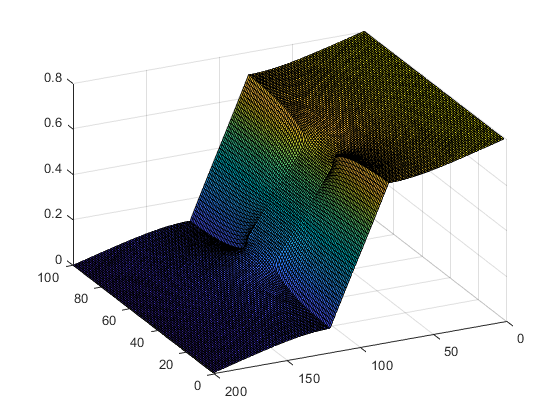

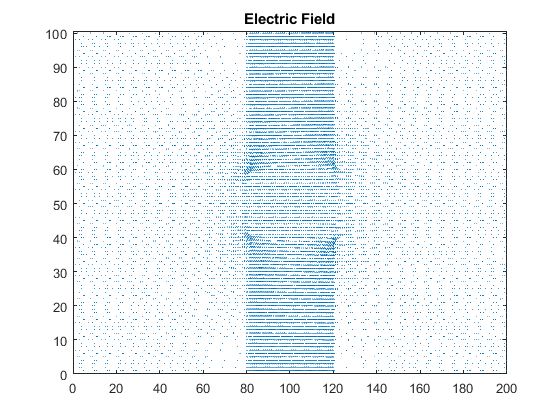

% MC Settings
eCount = 1000;      % Total number of electrons
nt = 1000;          % Simulation steps
tStop = nt * dt;	% Stop Time

% Bottleneck Settings
% Addition of box colliders to the sim
toggleDiffusive = 1; % 0 - Specular, 1 - Diffusive
% Providing opposing corners of desired boxes
box = [ % x1,y1, x2, y2 (Per box)
    0.8, 0, 1.2, 0.4;
    0.8, 0.6, 1.2, 1;
    ].*1e-7;

% Electric Field Settings
voltage = 0.8;  % in volts
nx = 200;       % Number of divisions in X
ny = 100;       % ... in Y
boxL = 40;      % length of box along X
boxW = 40;      % width of box along Y
sigma = 0.001;  % Conductivity in the box
V = Assignment2_Q2(nx, ny, boxL, boxW, sigma) * voltage;
vMap = reshape(V, [ny nx]);    % Reshaping Vector to a matrix
[Ex,Ey] = gradient(-vMap);
Ex = Ex ./ (Length/nx);    Ey = Ey ./ (Width/ny);    % Scaling E-Field

% Potential Surface Map
vMap = reshape(V, [ny nx]);    % Reshaping Vector to a matrix
figure('name', 'Voltage - FD Solution'), surf(vMap'); % Plotting

% Electric Field
figure('name', 'Electric Field');
quiver(Ex,Ey,1.1), title('Electric Field');


% Initializing all electrons with position and velocity
% Electron object stores position, velocity and drift
eObj = struct('x', 0, 'y', 0, 'vx', 0, 'vy', 0, ...
                        'vm', 0, 'vdx', 0, 'vdy', 0);
eCol = rand(eCount,3);   % Random colours for plotting
for i = 1 : eCount
    eObj(i).x = rand()*Length;
    eObj(i).y = rand()*Width;
    for b = 1:size(box,1)
        while eObj(i).x <= max(box(b,1),box(b,3)) && ...
                eObj(i).x >= min(box(b,1),box(b,3)) && ...
                eObj(i).y <= max(box(b,2),box(b,4)) && ...
                eObj(i).y >= min(box(b,2),box(b,4))
            eObj(i).x = rand()*Length;
            eObj(i).y = rand()*Width;
        end
    end
    eObj(i).vx = (sqrt(vT^2 / 2)*randn(1,1));
    eObj(i).vy = (sqrt(vT^2 / 2)*randn(1,1));
    eObj(i).vm = sqrt(eObj(i).vx^2 + eObj(i).vy^2);
end

% Simulation loop
figure('name', 'MC Simulation');
t = 0;          % Init time
counter = 2;    % Init Sim Counter
while t < tStop
    t = t + dt;	% Incrementing Time
    
    % binning x and y coordinates
    [xpartbin, e] = discretize([eObj(:).x], nx);
    [ypartbin, e] = discretize([eObj(:).y], ny);
    
    prevX = [eObj(:).x];    % Previous X location
    prevY = [eObj(:).y];    % Previous Y location
    for i = 1 : eCount
        
        % Updating position
        eObj(i).x = prevX(i) + eObj(i).vx * dt;
        eObj(i).y = prevY(i) + eObj(i).vy * dt;
        
        % Scattering effect - Randomize direction/magnitude of velocity
        % Probability of scattering based on p.
        if pScatter > rand() && toggleScatter	% 'if true'
            eObj(i).vx = (sqrt(vT^2 / 2)*randn(1,1));
            eObj(i).vy = (sqrt(vT^2 / 2)*randn(1,1));
        end
        
        % Updating the velocities with the effect of E-Field
        Fx = qe * Ex(ypartbin(i), xpartbin(i));
        Fy = qe * Ey(ypartbin(i), xpartbin(i));
        eObj(i).vx = eObj(i).vx + 1/2*Fx/mn*dt;
        eObj(i).vy = eObj(i).vy + 1/2*Fy/mn*dt;
        
        % Drift velocity calculation
        dx = eObj(i).x - prevX(i);
        eObj(i).vdx = dx/dt;
        
        % Magnitude of velocity
        eObj(i).vm = sqrt(eObj(i).vx.^2 + eObj(i).vy.^2);
        
        % Box Collider Conditions.
        for b = 1:size(box,1)
            % Plotting the Boxes on the plot
            if counter == 2 % Only plot once
                boxX = [box(b,1), box(b,1), box(b,3), box(b,3), box(b,1)];
                boxY = [box(b,2), box(b,4), box(b,4), box(b,2), box(b,2)];
                fill(boxX, boxY, 'k');
            end

            % Boundaries defined by coordinates
            boundL = min(box(b,1),box(b,3));    % Left Wall
            boundR = max(box(b,1),box(b,3));    % Right Wall
            boundT = max(box(b,2),box(b,4));    % Top Wall
            boundB = min(box(b,2),box(b,4));    % Bottom Wall

            % Conditions set by boundaires
            condL = prevX(i) <= boundL && eObj(i).x >= boundL;
            condR = prevX(i) >= boundR && eObj(i).x <= boundR;
            condB = prevY(i) <= boundB && eObj(i).y >= boundB;
            condT = prevY(i) >= boundT && eObj(i).y <= boundT;
            % Corner Cases
            condTC = condT && condR || condT && condL;
            condBC = condB && condR || condB && condL;

            % Checking Left and Right of the box First. 
            % Start by confirming if within Top and Bottom Boundaries
            if eObj(i).y <= boundT && eObj(i).y >= boundB
                if condL || condR || condTC || condBC
                    if toggleDiffusive == 1 % If diffusion is toggled
                        posX = eObj(i).vx >= 0;	% Storing sign
                        posY = eObj(i).vy >= 0;
                        % re-thermalizing
                        eObj(i).vx = (sqrt(vT^2 / 2)*randn(1,1));
                        eObj(i).vy = (sqrt(vT^2 / 2)*randn(1,1));
                        % checking sign
                        if (eObj(i).vx >= 0) == posX
                            eObj(i).vx = -eObj(i).vx;
                        end
                        if (eObj(i).vy >= 0) ~= posY
                            eObj(i).vy = -eObj(i).vy;
                        end
                    else
                        eObj(i).vx = -eObj(i).vx;   % Just inverting
                    end
                    if condL    % Shifting reflection point
                        eObj(i).x = boundL - (eObj(i).x - boundL);
                    else
                        eObj(i).x = boundR + (boundR - eObj(i).x);
                    end
                end
            end
            % Checking Top and Bottom of the box. 
            % Start by confirming if within Left and Right Boundaries
            if eObj(i).x <= boundR && eObj(i).x >= boundL
                if condT || condB
                    if toggleDiffusive == 1
                        posX = eObj(i).vx >= 0;
                        posY = eObj(i).vy >= 0;  % Storing sign
                        % re-thermalizing
                        eObj(i).vx = (sqrt(vT^2 / 2)*randn(1,1));
                        eObj(i).vy = (sqrt(vT^2 / 2)*randn(1,1));
                        % checking sign
                        if (eObj(i).vx >= 0) ~= posX
                            eObj(i).vx = -eObj(i).vx;
                        end
                        if (eObj(i).vy >= 0) == posY
                            eObj(i).vy = -eObj(i).vy;
                        end
                    else
                        eObj(i).vy = -eObj(i).vy;
                    end
                    if condB    % Shifting reflection point
                        eObj(i).y = boundB - (eObj(i).y - boundB);
                    else
                        eObj(i).y = boundT + (boundT - eObj(i).y);
                    end
                end
            end
        end
        
        
        % Top and Bottom Boundary Conditions
        if eObj(i).y > Width % y = 200nm boundary 
            diff = eObj(i).y - Width;
            eObj(i).y = Width - diff;
            eObj(i).vy = -eObj(i).vy;
        end
        if eObj(i).y < 0   % y = 0nm boundary
            diff = -eObj(i).y;
            eObj(i).y = diff;
            eObj(i).vy = -eObj(i).vy;
        end
        
        % Plotting Electrons
        if (i <= ePlotted)
            % Plotting previous and current position
            p = plot( [prevX(i), eObj(i).x], ...
                [prevY(i), eObj(i).y], ...
                'LineWidth', 1.5);
            p.Color = eCol(i,:);        % Attributing unique colour
            axis([0,Length,0,Width]);	% Plot Axis' set
            title('Electron Trajectories');
            hold on
        end
        
        % Left hand and Right hand side Boundary Conditions
        if eObj(i).x > Length   % x = 100nm boundary
            eObj(i).x = eObj(i).x - Length;
        end
        if eObj(i).x < 0   % x = 0nm boundary
            eObj(i).x = eObj(i).x + Length;
        end
        
    end
    pause(0.0001);	% Delay for animation
    
    counter = counter + 1;      % Incrementing Sim Counter
end

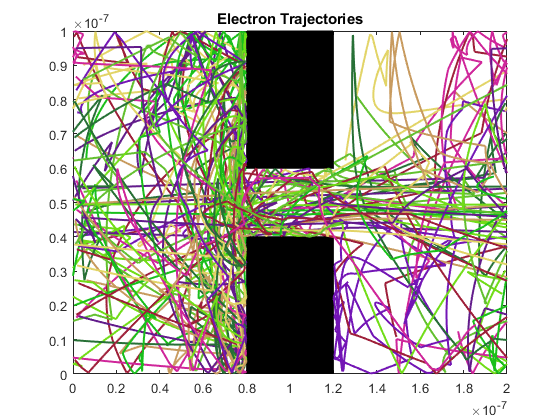

hold off

### Part 3: Extracting simple parameters using the combined solver

#### a) Density of Electrons

The following is a density map of the electrons from the simulation performed in the previous section.

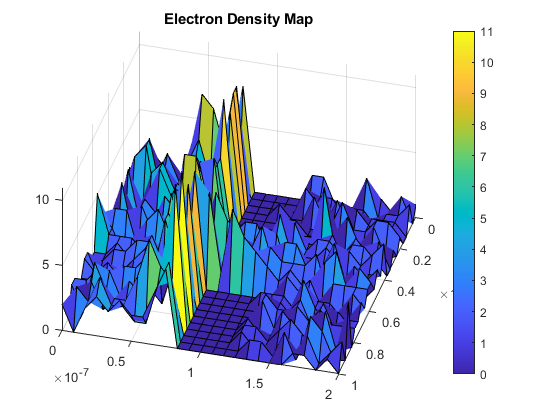

% Plotting an Electron Density map
ptsX = linspace(0, Length, 26);
ptsY = linspace(0, Width, 26);
[X,Y] = meshgrid(linspace(0, Length, 25), linspace(0, Width, 25));
N = histcounts2([eObj(:).y], [eObj(:).x], ptsY, ptsX);  % Binning
figure()
surf(Y,X,N),colorbar,title('Electron Density Map');

view([105.6 48.6])

The denisty map gives a better picture of how the electrons crowd around the barriers. The electrons on the left side where the potential is higher overall have a much higher concentration in comparison to the right side.

#### b) Effect of the bottle neck on the current in the system

Various gap widths were simulated to observe the average current in the system. The following plot demonstrate the average current ofer time for each bottle neck as well as a plot showing the trend as the gap increases. Seven different gap sizes are simulated over 150 time steps with 10000 electrons.

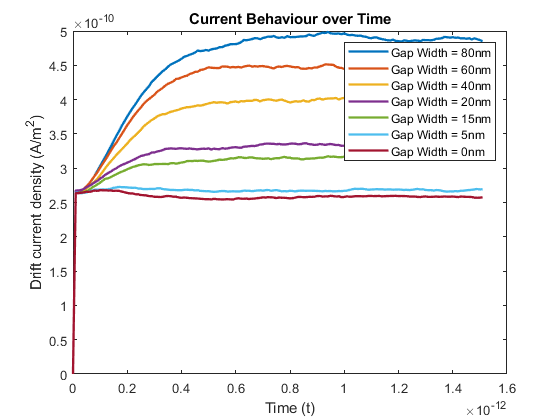

eCount = 10000;      % Total number of electrons
dt = 10e-15;        % Time step 10fs -> -(Width/100)/vT
nt = 150;           % Simulation steps
tStop = nt * dt;	% Stop Time

% Bottleneck Settings
% Addition of box colliders to the sim
toggleDiffusive = 1; % 0 - Specular, 1 - Diffusive
% Providing opposing corners of desired boxes

b1 = [ % x1,y1, x2, y2 (Per box)   40x10
    0.8, 0, 1.2, 0.1;
    0.8, 0.9, 1.2, 1;
    ].*1e-7;

b2 = [ % x1,y1, x2, y2 (Per box)   40x20
    0.8, 0, 1.2, 0.2;
    0.8, 0.8, 1.2, 1;
    ].*1e-7;

b3 = [ % x1,y1, x2, y2 (Per box)   40x30
    0.8, 0, 1.2, 0.3;
    0.8, 0.7, 1.2, 1;
    ].*1e-7;

b4 = [ % x1,y1, x2, y2 (Per box)   40x40
    0.8, 0, 1.2, 0.4;
    0.8, 0.6, 1.2, 1;
    ].*1e-7;

b5 = [ % x1,y1, x2, y2 (Per box)   40x42.5
    0.8, 0, 1.2, 0.425;
    0.8, 0.575, 1.2, 1;
    ].*1e-7;

b6 = [ % x1,y1, x2, y2 (Per box)   40x47.5
    0.8, 0, 1.2, 0.475;
    0.8, 0.525, 1.2, 1;
    ].*1e-7;

b7 = [ % x1,y1, x2, y2 (Per box)   40x50
    0.8, 0, 1.2, 0.5;
    0.8, 0.5, 1.2, 1;
    ].*1e-7;

boxes = [b1; b2; b3; b4; b5; b6; b7];
boxesW = [10 20 30 40 42.5 47.5 50];

wcount = 0;      % counter for selecting box width
for j = 1 :2: size(boxes,1)
    wcount=wcount+1;
    box = [boxes(j,:,:);boxes(j+1,:,:)];
    
    
    % Electric Field Settings
    voltage = 0.8;  % in volts
    nx = 200;       % Number of divisions in X
    ny = 100;       % ... in Y
    boxL = 40;      % length of box along X
    boxW = boxesW(wcount);      % width of box along Y
    sigma = 0.001;  % Conductivity in the box
    V = Assignment2_Q2(nx, ny, boxL, boxW, sigma) * voltage;
    vMap = reshape(V, [ny nx]);    % Reshaping Vector to a matrix
    [Ex,Ey] = gradient(-vMap);
    Ex = Ex ./ (Length/nx);    Ey = Ey ./ (Width/ny);    % Scaling E-Field

    % Initializing all electrons with position and velocity
    % Electron object stores position, velocity and drift
    eObj = struct('x', 0, 'y', 0, 'vx', 0, 'vy', 0, 'vm', 0, 'vd', 0);
    for i = 1 : eCount
        eObj(i).x = rand()*Length;
        eObj(i).y = rand()*Width;
        for b = 1:size(box,1)
            while eObj(i).x <= max(box(b,1),box(b,3)) && ...
                    eObj(i).x >= min(box(b,1),box(b,3)) && ...
                    eObj(i).y <= max(box(b,2),box(b,4)) && ...
                    eObj(i).y >= min(box(b,2),box(b,4))
                eObj(i).x = rand()*Length;
                eObj(i).y = rand()*Width;
            end
        end
        eObj(i).vx = (sqrt(vT^2 / 2)*randn(1,1));
        eObj(i).vy = (sqrt(vT^2 / 2)*randn(1,1));
        eObj(i).vm = sqrt(eObj(i).vx^2 + eObj(i).vy^2);
    end

    % Simulation loop
    t = 0;          % Init time
    counter = 2;    % Init Sim Counter
    while t < tStop
        t = t + dt;	% Incrementing Time

        % binning x and y coordinates
        [xpartbin, e] = discretize([eObj(:).x], nx);
        [ypartbin, e] = discretize([eObj(:).y], ny);

        prevX = [eObj(:).x];    % Previous X location
        prevY = [eObj(:).y];    % Previous Y location
        for i = 1 : eCount

            % Updating position
            eObj(i).x = prevX(i) + eObj(i).vx * dt;
            eObj(i).y = prevY(i) + eObj(i).vy * dt;

            % Scattering effect - Randomize direction/magnitude of velocity
            % Probability of scattering based on p.
            if pScatter > rand() && toggleScatter	% 'if true'
                eObj(i).vx = (sqrt(vT^2 / 2)*randn(1,1));
                eObj(i).vy = (sqrt(vT^2 / 2)*randn(1,1));
            end

            % Updating the velocities with the effect of E-Field
            Fx = qe * Ex(ypartbin(i), xpartbin(i));
            Fy = qe * Ey(ypartbin(i), xpartbin(i));
            eObj(i).vx = eObj(i).vx + 1/2*Fx/mn*dt;
            eObj(i).vy = eObj(i).vy + 1/2*Fy/mn*dt;

            % Drift velocity calculation
            dx = eObj(i).x - prevX(i);
            dy =  eObj(i).y - prevY(i);
            eObj(i).vd = sqrt((dx/dt)^2 + (dy/dt)^2);

            % Magnitude of velocity
            eObj(i).vm = sqrt(eObj(i).vx.^2 + eObj(i).vy.^2);

            % Box Collider Conditions.
            for b = 1:size(box,1)

                % Boundaries defined by coordinates
                boundL = min(box(b,1),box(b,3));    % Left Wall
                boundR = max(box(b,1),box(b,3));    % Right Wall
                boundT = max(box(b,2),box(b,4));    % Top Wall
                boundB = min(box(b,2),box(b,4));    % Bottom Wall

                % Conditions set by boundaires
                condL = prevX(i) <= boundL && eObj(i).x >= boundL;
                condR = prevX(i) >= boundR && eObj(i).x <= boundR;
                condB = prevY(i) <= boundB && eObj(i).y >= boundB;
                condT = prevY(i) >= boundT && eObj(i).y <= boundT;
                % Corner Cases
                condTC = condT && condR || condT && condL;
                condBC = condB && condR || condB && condL;

                % Checking Left and Right of the box First. 
                % Start by confirming if within Top and Bottom Boundaries
                if eObj(i).y <= boundT && eObj(i).y >= boundB
                    if condL || condR || condTC || condBC
                        if toggleDiffusive == 1 % If diffusion is toggled
                            posX = eObj(i).vx >= 0;	% Storing sign
                            posY = eObj(i).vy >= 0;
                            % re-thermalizing
                            eObj(i).vx = (sqrt(vT^2 / 2)*randn(1,1));
                            eObj(i).vy = (sqrt(vT^2 / 2)*randn(1,1));
                            % checking sign
                            if (eObj(i).vx >= 0) == posX
                                eObj(i).vx = -eObj(i).vx;
                            end
                            if (eObj(i).vy >= 0) ~= posY
                                eObj(i).vy = -eObj(i).vy;
                            end
                        else
                            eObj(i).vx = -eObj(i).vx;   % Just inverting
                        end
                        if condL    % Shifting reflection point
                            eObj(i).x = boundL - (eObj(i).x - boundL);
                        else
                            eObj(i).x = boundR + (boundR - eObj(i).x);
                        end
                    end
                end
                % Checking Top and Bottom of the box. 
                % Start by confirming if within Left and Right Boundaries
                if eObj(i).x <= boundR && eObj(i).x >= boundL
                    if condT || condB
                        if toggleDiffusive == 1
                            posX = eObj(i).vx >= 0;
                            posY = eObj(i).vy >= 0;  % Storing sign
                            % re-thermalizing
                            eObj(i).vx = (sqrt(vT^2 / 2)*randn(1,1));
                            eObj(i).vy = (sqrt(vT^2 / 2)*randn(1,1));
                            % checking sign
                            if (eObj(i).vx >= 0) ~= posX
                                eObj(i).vx = -eObj(i).vx;
                            end
                            if (eObj(i).vy >= 0) == posY
                                eObj(i).vy = -eObj(i).vy;
                            end
                        else
                            eObj(i).vy = -eObj(i).vy;
                        end
                        if condB    % Shifting reflection point
                            eObj(i).y = boundB - (eObj(i).y - boundB);
                        else
                            eObj(i).y = boundT + (boundT - eObj(i).y);
                        end
                    end
                end
            end

            % Top and Bottom Boundary Conditions
            if eObj(i).y > Width % y = 200nm boundary 
                diff = eObj(i).y - Width;
                eObj(i).y = Width - diff;
                eObj(i).vy = -eObj(i).vy;
            end
            if eObj(i).y < 0   % y = 0nm boundary
                diff = -eObj(i).y;
                eObj(i).y = diff;
                eObj(i).vy = -eObj(i).vy;
            end

            % Left hand and Right hand side Boundary Conditions
            if eObj(i).x > Length   % x = 100nm boundary
                eObj(i).x = eObj(i).x - Length;
            end
            if eObj(i).x < 0   % x = 0nm boundary
                eObj(i).x = eObj(i).x + Length;
            end

        end

        % Calculating drift current density over time
        Jn(:,counter) = qe*eCount*mean([eObj(:).vd]);
        Time(:,counter) = t;        % Recording time in a vector
        counter = counter + 1;      % Incrementing Sim Counter
    end
    avgJn(:,wcount) = mean(Jn);
    % Plotting drift current density over time
    plot(Time, Jn, 'LineWidth',1.75);
    hold on
    Time = 0; Jn = 0;
end
xlabel('Time (t)'), ylabel('Drift current density (A/m^2)');
legend('Gap Width = 80nm', 'Gap Width = 60nm', ...
    'Gap Width = 40nm',...
    'Gap Width = 20nm', 'Gap Width = 15nm',...
    'Gap Width = 5nm', 'Gap Width = 0nm')
title('Current Behaviour over Time');
hold off

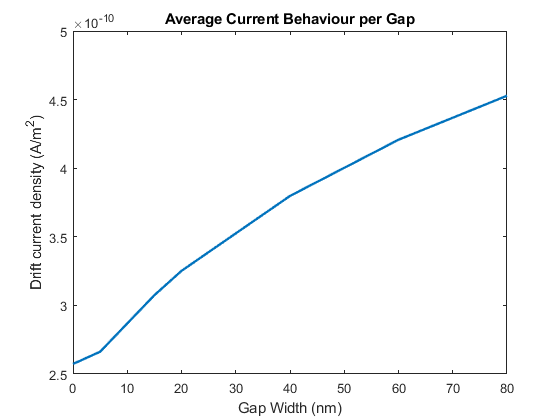

figure()
plot([80 60 40 20 15 5 0], avgJn, 'LineWidth',1.75);
xlabel('Gap Width (nm)'), ylabel('Drift current density (A/m^2)');
title('Average Current Behaviour per Gap');

The bottle neck gap width has a large effect on the average current in the system. As the gap width approaches a cut-off the average current in the system decreases by about half of the total magnitude possible. The reason for this is due to the average being taken across the whole region, even though there will be little to no flow across the boundry depending on the gap. There is effectively no variation of the drift current over time on the cut off side. With that said, the highest attainable magnitude can be observed when the gap width is very small, the electrons that cross the boundry are essentially propelled through, as long as it does not scatter. To conclude, the relationship shows that if the gap width increases more variation of the drift current can be observed which increases the current density across the region.

#### c) Next Steps for the Simulator

The following is a list of possible enhancements and modifications to increase accuracy.

- Increasing efficiency and scope of the simulator would allow for more particles to be simulated which would in turn increase accuracy.

- Including the effect of more sophisticated gaps could prove useful in modelling real structures.

- Improving the randomness to account for various factors. Example of this could be process variation.

- Including wave propagation through the material.

- Including Quantum Tunneling to support the wave propagation as well as increase accuracy.

- Include the effect of more dynamic regions which could model structures which shapes can change.

- Include a third dimension to give a more accuracte representation of what the material will do in the real world.